# Example of Fmincon

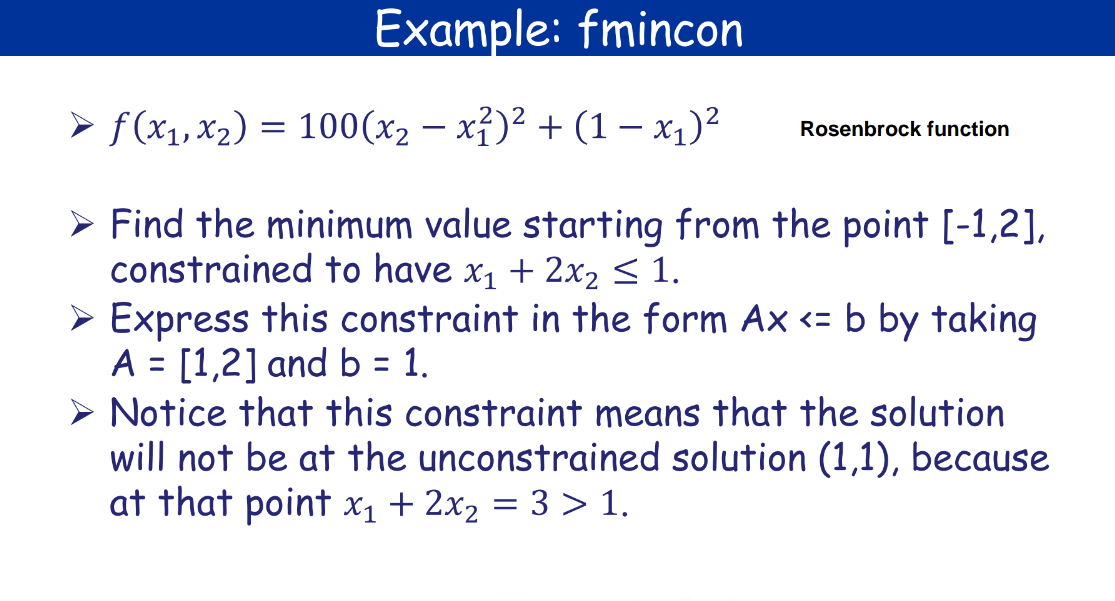

clear;clc;
fun=@(x)100.*(x(2)-x(1).^2).^2+(1-x(1)).^2;
x0=[-1 2];
A=[1 2];
b=1;
options=optimset("Display",'off');
x=fmincon(fun,x0,A,b,[],[],[],[],[],options);
x

x =     0.5022    0.2489


## Example 1

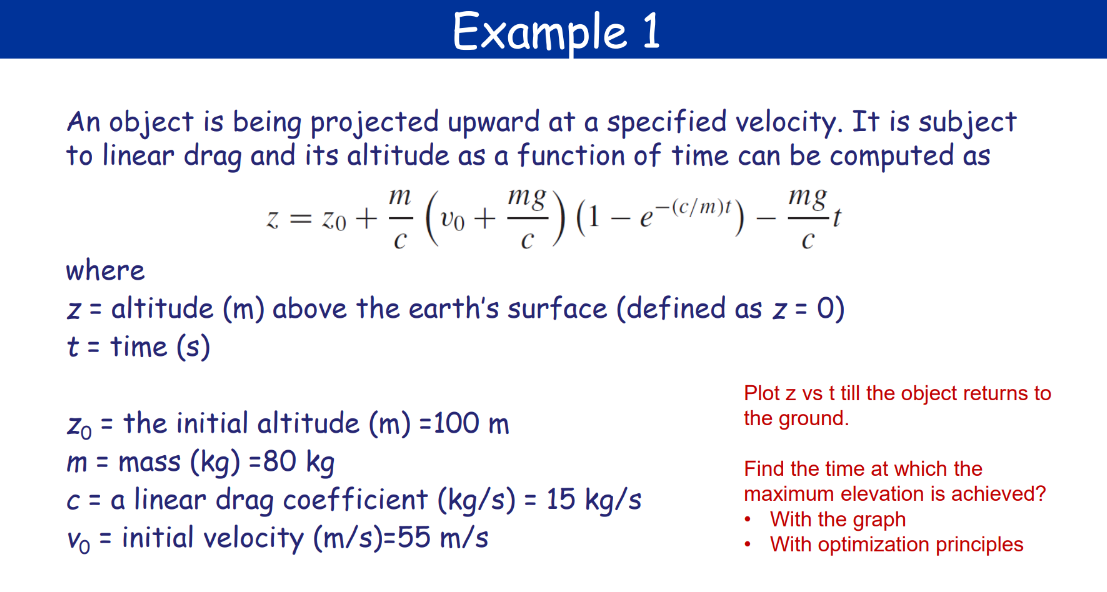

% Givens
clear;clc;
z0=100;m=80;c=15;v0=55;g=9.81;

## Optimizing

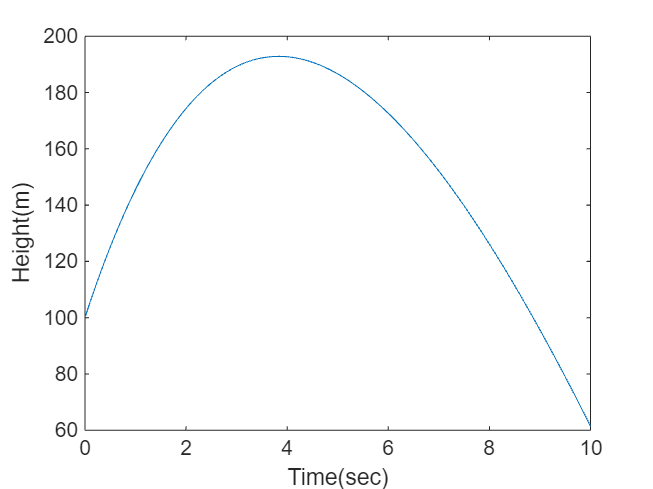

res=@(t)(-(z0+m.*(v0+m.*g./c)./c.*(1-exp(-c.*t./m))-m.*g.*t./c));
t=linspace(0,10,100);
plot(t,-res(t))
xlabel("Time(sec)")
ylabel("Height(m)")

[time_t,r2]=fmincon(res,0,-1,0,[],[],[],[],[],optimset("Display",'off'));
disp("Maximum Height is "+(-r2)+"m")

Maximum Height is 192.8609m


## Example 2

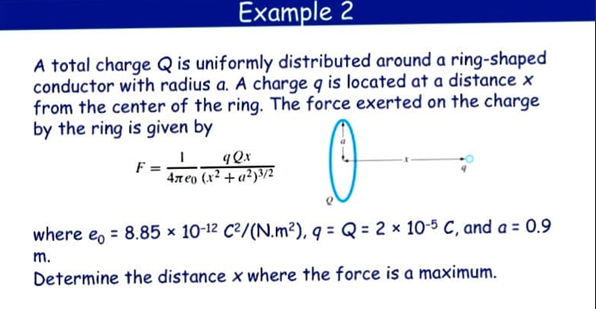

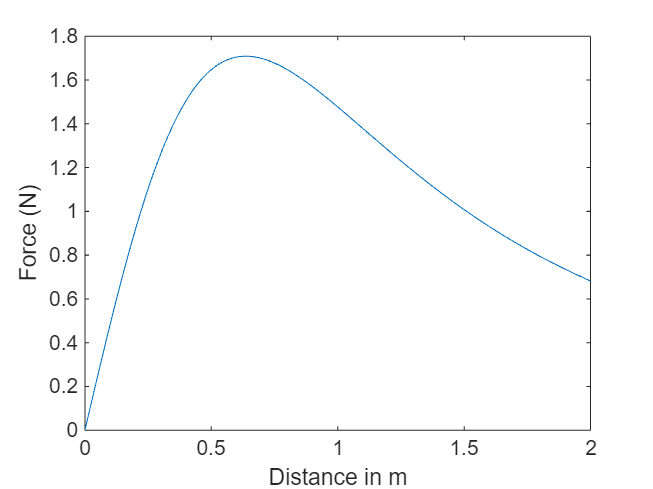

% Givens
e0=8.85e-12;q=2e-5;Q=2e-5;a=0.9;
% Solving
z=@(x)(-(q.*Q.*x)./(4.*pi.*e0.*(x.^2+a.^2).^1.5));
res=fmincon(z,0,-1,0,[],[],[],[],[],optimset('Display','off'));

x=linspace(0,2,100);
plot(x,-z(x));
xlabel("Distance in m");
ylabel("Force (N)")

disp("The point at which the force is maximum is: "+res+"m");

The point at which the force is maximum is: 0.6364m


disp("Maximum force is: "+(-z(res))+"N");

Maximum force is: 1.7091N


## CSTR Trains wala Bada Question

clear;clc;

Vin=[5 5 5 5];
A=[1 1 1 1];
b=20;
%Given
q=71/3600;n=2.5;k=6.25e-3;c0=20;
[res,c4]=fmincon(@(V)vKaFunc(c0,V,q,k,n),Vin,[],[],A,b,[0 0 0 0],[20 20 20 20],[],optimset('Display','Off'));
disp("Minimum c4 is: "+vKaFunc(c0,res,q,k,n))

Minimum c4 is: 0.39624


disp("Volume at this:")

Volume at this:


disp(res)

    2.2423    3.9227    5.8261    8.0090



function c4=vKaFunc(c0,V,q,k,n)
    inGuess=[2 2 2 2];options=optimset('Display','Off');
    cc=fsolve(@(c)cfinder(c0,c,V,q,k,n),inGuess,options);
    c4=cc(4);
end

function cc=cfinder(c0,c,V,q,k,n)
    cc(1)=q*(c0  -c(1))-k*V(1)*c(1)^n;
    cc(2)=q*(c(1)-c(2))-k*V(2)*c(2)^n;
    cc(3)=q*(c(2)-c(3))-k*V(3)*c(3)^n;
    cc(4)=q*(c(3)-c(4))-k*V(4)*c(4)^n;
end


## T-Shirt wala Example

clear;clc;
res=@(x)(-(10*x(1)+15*(x(2))))

res = function_handle with value:
    @(x)(-(10*x(1)+15*(x(2))))



A=[2 2;1 4];
b=[60;60]

b =     60
    60


[x,outpu]=fmincon(res,[0,0],A,b,[],[],[],[60,60],[],optimset("Display",'off'));
disp(x)

   20.0000   10.0000



disp(-outpu)

  350.0000



## WWT Plant

% Givens
clear; clc;
P = [1e9, 2e9, 4e9, 2.5e9];
d = [2, 2, 4, 4] .* 1e-6;
R13 = 0.5; R23 = 0.35; R34 = 0.6;
Q13 = 1e7; Q23 = 5e7; Q34 = 11e7; Q45 = 25e7;

% Cost function
cost = @(c) total_cost(c, P, d, R13, R23, R34, Q13, Q23, Q34, Q45);

% Initial guess
c0 = [20, 20, 20, 20];

% Lower and upper bounds
lb = [0, 0, 0, 0];
ub = [20, 20, 20, 20];

% Optimization
res = fmincon(cost, c0, [], [], [], [], lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Supporting functions
function totcos = total_cost(c, P, d, R13, R23, R34, Q13, Q23, Q34, Q45)
    % Calculate x values
    x = [
        1 - Q13 * c(1) / P(1);
        1 - Q23 * c(2) / P(2);
        1 - Q34 * c(3) / P(3) + Q23 * R23 * c(2) + Q13 * R13 * c(1);
        1 - Q45 * c(4) / P(4) + Q34 * R34 * c(3)
    ]';

    % Total cost calculation
    totcos = sum(P .* x .* d);
end


## chatgpt

% Data
clear; clc;
P = [1e9, 2e9, 4e9, 2.5e9]; % Waste generated by each city (mg/day)
d = [2, 2, 4, 4] .* 1e-6;   % Cost of treatment ($/mg)
Q = [1e7, 5e7, 11e7, 25e7]; % Flow rates (L/day)
R = [0.5, 0.35, 0.6];       % Reduction factors (R13, R23, R34)

% Objective function (minimize cost)
cost = @(x) sum(P .* x .* d);

% Nonlinear constraints for pollutant concentration
function [cineq, ceq] = pollutant_constraints(x, P, Q, R)
    c1 = P(1) * (1 - x(1)) / Q(1);
    c2 = P(2) * (1 - x(2)) / Q(2);
    c3 = (P(3) * (1 - x(3)) + Q(2) * R(2) * c2 + Q(1) * R(1) * c1) / Q(3);
    c4 = (P(4) * (1 - x(4)) + Q(3) * R(3) * c3) / Q(4);
    cineq = [c1 - 20; c2 - 20; c3 - 20; c4 - 20]; % Ensure all ci <= 20
    ceq = []; % No equality constraints
end

% Initial guess
x0 = [0.5, 0.5, 0.5, 0.5]; % Starting fraction values

% Bounds
lb = [0, 0, 0, 0];
ub = [1, 1, 1, 1];

% Optimization
options = optimoptions('fmincon', 'Display', 'iter');
[x_opt, cost_opt] = fmincon(@(x) cost(x), x0, [], [], [], [], lb, ub, ...
                            @(x) pollutant_constraints(x, P, Q, R), options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.600000e+04    3.000e+01    4.853e+03
    1      10    1.174845e+04    1.595e+01    2.660e+03    5.177e-01
    2      15    1.223889e+04    5.220e+00    2.845e+02    1.089e-01
    3      20    1.260030e+04    0.000e+00    5.660e+00    1.576e-01
    4      25    1.260000e+04    0.000e+00    1.796e-02    8.415e-05
    5      30    1.260000e+04    0.000e+00    1.769e-04    5.368e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a


% Display results
disp('Optimal fraction of waste removed (x):');

Optimal fraction of waste removed (x):


disp(x_opt);

    0.9059    0.5000    0.5493    0.0000



disp('Minimum cost ($):');

Minimum cost ($):


disp(cost_opt);  

   1.2600e+04

